# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 3

## 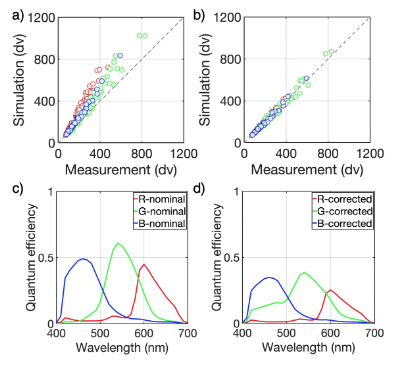

Fig. 3. Sensor spectral quantum efficiency calibration. (a) Scatter plot comparing measured and simulated RGB values of the MCC based on nominal color filter quantum efficiency. (b) Scatter plot comparing measured and simulated RGB values after correction for cross-talk and channel gain. (c) Nominal color filter quantum efficiency and (d) quantum efficiency after correction

%% Initialization
tmp = load('p4aLensVignet_dc_p55_pos1.mat', 'pixel4aLensVignetSlope');
vignetting = tmp.pixel4aLensVignetSlope;

%
qeDir = fullfile(cboxRootPath, 'data', 'measurement', 'QEcalibration');
%% First check the accuracy in the middle center with everything on 
% Read in mean meas
illuminantType = {'A', 'day', 'cwf'};
pos = {'midcenter'};
cornerPointsMeas = {[1858 1408 2229 1656],...
                    [1858 1408 2229 1656],...
                    [1858 1408 2229 1656]};
nFrames = numel(illuminantType) * numel(pos);
imgNames = cell(1, nFrames);
illuminants = cell(1, nFrames);
% Counter
cnt = 1;
for ii=1:numel(illuminantType)
    thisIllu = illuminantType{ii};
    
    curIlluDir = fullfile(qeDir, thisIllu);
    
    for jj=1:numel(pos)
        thisDngFile = dir(fullfile(curIlluDir, pos{jj}, '*.dng'));
        imgNames{cnt} = fullfile(curIlluDir, pos{jj},thisDngFile(1).name);
        illuminants{cnt} = thisIllu;
        cnt = cnt + 1;
    end
end

% Get rgb mean in mid center
rgbMeanMeasMidCenter = zeros(nFrames * 24, 3);
for ii=1:numel(imgNames)
    thisCropMeas = cornerPointsMeas{ii};
    thisIllu = illuminants{ii};
    % Get the mean rgb for this sensor
    [thisSensorMeas, thisInfo, thisRGBMeanMeas, ~] = cbMccChipsDV(imgNames{ii},...
                                                              'corner point', thisCropMeas,...
                                                              'vignetting', vignetting);
    rgbMeanMeasMidCenter((ii-1) * 24+1:ii*24,:) = thisRGBMeanMeas;
end

Black border
Black border
Black border




%% Calculate simulate signals
% Precompute the illumination scene and oi
wave = 390:10:710;
lightNameA   = 'illA-20201023.mat'; % Tungsten (A)
lightNameCWF = 'illCWF-20201023.mat'; % CWF
lightNameDay = 'illDay-20201023.mat'; % Daylight
patchSize = 32;
[sceneA, oiA] = cbMccSceneOISim('illuminant', lightNameA, 'wave', wave,...
                                'patch size', patchSize);
[sceneCWF, oiCWF] = cbMccSceneOISim('illuminant', lightNameCWF, 'wave', wave,...
                                'patch size', patchSize);       
[sceneDay, oiDay] = cbMccSceneOISim('illuminant', lightNameDay, 'wave', wave,...
                                'patch size', patchSize);
                            
cornerPointsSim = [165 160 1089 770];
sensorSimCor = cbDNGRead(imgNames{3}, 'demosaic', false);
blkLvl = sensorGet(sensorSimCor, 'black level');
% Now compute the sensor response without color filter correction
sensorSimNoCor = cbDNGRead(imgNames{3}, 'demosaic', false, 'transcolorfilter', false);
[~, rgbMeanANoCor, ~] = cbMccSensorSim(oiA, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanDayNoCor, ~] = cbMccSensorSim(oiDay, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanCWFNoCor, ~] = cbMccSensorSim(oiCWF, sensorSimNoCor, cornerPointsSim);

Black border


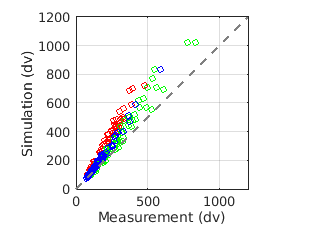


rgbMeanSimNoCorMidCenter = [rgbMeanANoCor;rgbMeanDayNoCor;rgbMeanCWFNoCor];
% Make sure the simulated sensor data w/o correction DOES NOT match the measurement
ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimNoCorMidCenter(:,1)+ blkLvl,'ro','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimNoCorMidCenter(:,2)+ blkLvl,'go','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimNoCorMidCenter(:,3)+ blkLvl,'bo','MarkerSize', 5); identityLine;
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');
xlim([0 1200]); ylim([0 1200])

% Get the black level

[~, rgbMeanACor, ~] = cbMccSensorSim(oiA, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanDayCor, ~] = cbMccSensorSim(oiDay, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanCWFCor, ~] = cbMccSensorSim(oiCWF, sensorSimCor, cornerPointsSim);

Black border


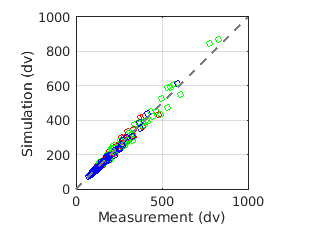


rgbMeanSimCorMidCenter = [rgbMeanACor;rgbMeanDayCor;rgbMeanCWFCor];

% Make sure the simulated sensor data match the measurement
ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimCorMidCenter(:,1)+ blkLvl,'ro', 'MarkerSize', 5); 
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimCorMidCenter(:,2)+ blkLvl,'go', 'MarkerSize', 5);
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimCorMidCenter(:,3)+ blkLvl,'bo', 'MarkerSize', 5);
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');

###  Quantum efficiency

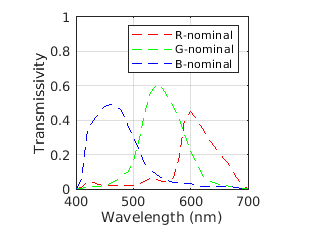

wave = sensorGet(sensorSimCor,'wave');
filterCorr = sensorGet(sensorSimCor, 'color filters');
filterOriRGB = sensorGet(sensorSimNoCor, 'color filters');
filterOriIr = sensorGet(sensorSimNoCor, 'irfilter');
filterOri = filterOriRGB .* filterOriIr;
ieNewGraphWin;
hold all;
plot(wave, filterOri(:,1), 'r--');
plot(wave, filterOri(:,2), 'g--');
plot(wave, filterOri(:,3), 'b--');
box on; xlim([400 700]); ylim([0 1]); grid on;
xlabel('Wavelength (nm)'); ylabel('Transmissivity');
legend('R-nominal', 'G-nominal', 'B-nominal');
axis square;

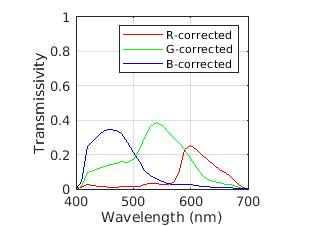


ieNewGraphWin;
hold all;
box on; xlim([400 700]); ylim([0 1]); grid on;
plot(wave, filterCorr(:,1), 'r');
plot(wave, filterCorr(:,2), 'g');
plot(wave, filterCorr(:,3), 'b');
xlabel('Wavelength (nm)'); ylabel('Transmissivity');
legend('R-corrected', 'G-corrected', 'B-corrected');
axis square;